## Alternating Least Squares (ALS) Algorithm

Consider the tensor $\underline{\mathbf{X}} \in C^{I\times J\times K}$, the CANDECOMP/PARAFAC (CP) decomposition aims to reprsent $\underline{\mathbf{X}}$ as a sum of one-rank tensor, that is


$$\underline{\mathbf{X}} =\sum_{r=1}^R \lambda_r {\mathbf{a}}_r \circ {\mathbf{b}}_r \circ {\mathbf{c}}_r$$


where ${\mathbf{a}}_r \in C^I$, ${\mathbf{b}}_r \in C^J$, ${\mathbf{c}}_r \in C^K$, $\lambda_r \in C$, and $R$ is the rank of the tensor $\underline{\mathbf{X}}$. The CP decomposition can be written more compactly as

$\left.\underline{\mathbf{X}} =\lbrack \Lambda ;\mathbf{A},\mathbf{B},\mathbf{C}\right\rbrack$,

being


$$\Lambda =\textrm{diag}\left(\lambda_r \right)$$



$$\mathbf{A}=\left\lbrack \begin{array}{cccc}
{\mathbf{a}}_1  & {\mathbf{a}}_2  & \cdots  & {\mathbf{a}}_R 
\end{array}\right\rbrack \in C^{I\times R}$$



$$\mathbf{B}=\left\lbrack \begin{array}{cccc}
{\mathbf{b}}_1  & {\mathbf{b}}_2  & \cdots  & {\mathbf{b}}_R 
\end{array}\right\rbrack \in C^{J\times R}$$



$$\mathbf{C}=\left\lbrack \begin{array}{cccc}
{\mathbf{c}}_1  & {\mathbf{c}}_2  & \cdots  & {\mathbf{c}}_R 
\end{array}\right\rbrack \in C^{K\times R}$$


Alternatively, one can write the above equation as

$\underline{\mathbf{X}} =\underline{\mathbf{I}} \times_1 \mathbf{A}\times_2 \mathbf{B}\times_3 \mathbf{C}$,

where $\underline{\mathbf{I}} \in C^{R\times R\times R}$ is a tensor whose elements is given by


$${\left\lbrack \underline{\mathbf{I}} \right\rbrack }_{i,j,k} \left\lbrace \begin{array}{ll}
=\lambda_r  & \textrm{if}\;i=j=k=r\\
=0 & \textrm{otherwise}
\end{array}\right.$$


Unfortunately, there is no direct method to calculate $R$. The rank tensor is determined numerically by iterative methods, which adjusts rank-R CP models.

Ideally, summing $k$ leading factors would yield a best rank-k approximation. In other words, this rank-$k$ approximation should minimize $\left\|\underline{\mathbf{X}} -\underline{\mathbf{Y}} \right\|$, where


$$\underline{\mathbf{Y}} =\sum_{r=1}^k \lambda_r {\mathbf{a}}_r \circ {\mathbf{b}}_r \circ {\mathbf{c}}_r$$


but that does not work for tensors as it does for matrix.

Therefore

- Given a value $R\in N$, how to compute the factors of the CP decomposition in order to the achive exact representation of $\underline{\mathbf{X}}$ (this is also called *rank decomposition*)?

- Given a value $k\in N$, how to compute the factors of the CP decomposition in order the achive the best $k$-rank approximation?

- If $R$ is unkown, how to compute it?

Ideally, the value $R$ is defined by fitting an initial CP model until the residual error reaches zero. The lowest number of one-rank tensors required for the exact equality is the value $R$. When $R$ or $k$ is given, an initial CP model is iterated over and over again until the fitting procedure attends to some benchmark.

The Alternating Least Squares (ALS) is an efficient method that performs CP decomposition iteratively. This method aims to solving the following non-linear least-square problem


$$\min_{\mathbf{A},\mathbf{B},\mathbf{C}} \left\|{\left\lbrack \underline{\mathbf{X}} \right\rbrack }_{\left(1\right)} -{\hat{\mathbf{A}} \left(\hat{\mathbf{C}} \triangle \hat{\mathbf{B}} \right)}^{\top } \right\|$$


The ALS method fixes $\hat{\mathbf{B}}$ and $\hat{\mathbf{C}}$ to solve for $\hat{\mathbf{A}}$, then fixes $\hat{\mathbf{A}}$ and $\hat{\mathbf{C}}$ to solve for $\hat{\mathbf{B}}$, then fixes $\hat{\mathbf{A}}$ and $\hat{\mathbf{B}}$ to solve for $\hat{\mathbf{C}}$, and continues to repeat the entire procedure until some convergence criterion is satisfied. Having fixed all but one matrix, the problem reduces to a trilinear least-squares problem.

Fixing all the matrices but $\mathbf{A}$, we have that the optimal solution is given by


$$\mathbf{A}\prime ={\left\lbrack \underline{\mathbf{X}} \right\rbrack }_{\left(1\right)} {{\left(\mathbf{C}\triangle \mathbf{B}\right)}^{\top } }^{\dagger } ={\left\lbrack \underline{\mathbf{X}} \right\rbrack }_{\left(1\right)} \left(\mathbf{C}\triangle \mathbf{B}\right){\left({\mathbf{C}}^{\top } \mathbf{C}\odot {\mathbf{B}}^{\top } \mathbf{B}\right)}^{\dagger }$$


Finally we normalize the columns of $\mathbf{A}\prime$ to get $\hat{\mathbf{A}}$, that is, one can define $\lambda_r =\left\|{\mathbf{a}}_r \prime \right\|$ such that ${\hat{\mathbf{a}} }_r ={\mathbf{a}}_r \prime /\lambda_r$. This definition avoids a mismatch between $\mathbf{A}$ and $\hat{\mathbf{A}}$ by a scalar.

For initialization of $\mathbf{A}\prime$, it is sensible to set it as the $R$ leading left singular vector of ${\left\lbrack \underline{\mathbf{X}} \right\rbrack }_{\left(1\right)}$.

## Problem 1

load cpd_tensor.mat A B C tenX

[tenlambda_hat, all_A_hat_normalized, all_nmse_X, n_iter] = als(tenX, size(A,2))

tenlambda_hat = tenlambda_hat(:,:,1) =

   18.0809         0         0
         0         0         0
         0         0         0


tenlambda_hat(:,:,2) =

         0         0         0
         0   10.8028         0
         0         0         0


tenlambda_hat(:,:,3) =

         0         0         0
         0         0         0
         0         0    3.9414


all_A_hat_normalized = 1×3 cell array
    {8×3 double}    {4×3 double}    {5×3 double}


all_nmse_X =     1.0552    0.0925    0.0487    0.0278    0.0173    0.0115    0.0081    0.0058    0.0042    0.0031    0.0023    0.0017    0.0013    0.0009    0.0007    0.0005    0.0004    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


n_iter = 33

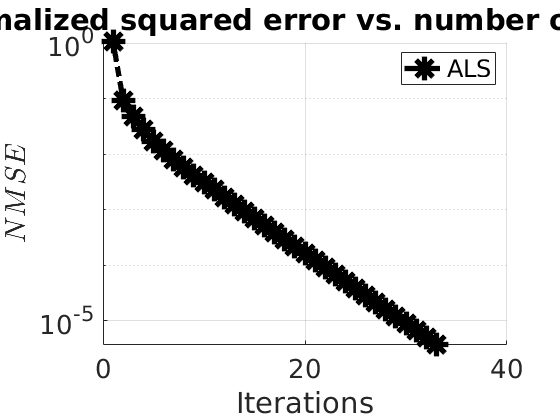

fig = figure();
ax = gca();
ax.FontName = 'Times New Roman';
ax.FontSize = 20;
ax.YAxis.Scale='log';
ax.XAxis.Label.String = 'Iterations';
ax.YAxis.Label.String = '$$NMSE$$';
ax.YAxis.Label.Interpreter = 'latex';
ax.Title.String = 'The normalized squared error vs. number of iterations';
grid on;
hold on;
plot(1:n_iter, all_nmse_X, 'LineWidth', 4, 'Color', "black","LineStyle","-.","Marker","*","MarkerSize",18);
legend('ALS');

Even though the $\underline{\mathbf{X}}$ tensor reconstruction error approaches 0, the factors $\hat{\mathbf{A}}$, $\hat{\mathbf{B}}$, and $\hat{\mathbf{C}}$ differ from the real ones by a permutation of their columns and, possibly, by scaling of -1. Therefore, the NMSE of the factors is not zero

get_each_nse = @(A, A_hat)(cellfun(@(x,y)(norm(x-y)/norm(x)), A, A_hat));
all_A_normalized = cellfun(@normc, {A, B, C}, 'UniformOutput', false);
nmse_all_A = get_each_nse(all_A_normalized, all_A_hat_normalized)

nmse_all_A =     1.3061    1.5740    1.6676


As the factor errors are actually the relevant aspect of the decomposition, $\hat{\mathbf{A}}$, $\hat{\mathbf{B}}$, and $\hat{\mathbf{C}}$ shall be permuted. Additionally, some of their columns must be multiplied by -1 in order to zero the error.

[all_A_final, tenlambda_final] = get_opt_permutation(all_A_normalized, tenX, all_A_hat_normalized, tenlambda_hat);

Finally we get an almost-zero error

nmse_all_A = get_each_nse(all_A_normalized, all_A_final);
nmse_A = nmse_all_A(1)

nmse_A = 5.0715e-06

nmse_B = nmse_all_A(2)

nmse_B = 5.7769e-06

nmse_C = nmse_all_A(2)

nmse_C = 5.7769e-06

## Problem 2

Let us define

$\underline{{\mathbf{X}}_0 } =\left\lbrack \begin{array}{ccc}
\mathbf{A} & \mathbf{B} & \mathbf{C}
\end{array}\right\rbrack$,

being$\mathbf{A}\in C^{I\times R}$, $\mathbf{B}\in C^{J\times R}$, $\mathbf{C}\in C^{K\times R}$, and $R=3$. The matrices have unit norm columns with elements randomly drawn from a Normal distribution with mean equal to 0 and variance equal to 1.

Consider a noisy term, $\underline{\mathbf{V}}$, with same dimension of $\underline{{\mathbf{X}}_0 }$, whose components come from a normal distribution with the same statistics. Let us further define $\underline{\mathbf{X}} =\underline{{\mathbf{X}}_0 } +\alpha \underline{\mathbf{V}}$ as the noisy version of $\underline{{\mathbf{X}}_0 }$, where $\alpha$ is a parameter that is setted depending on the signal-to-noise ration in the system, given by


$${\textrm{SNR}}_{\textrm{dB}} =10\;\log_{10} \;\left(\frac{{\left\|\underline{{\mathbf{X}}_0 } \right\|}_F^2 }{{\left\|\alpha \underline{\mathbf{V}} \right\|}_F^2 }\right)\to \alpha =\frac{{\left\|{\mathbf{X}}_0 \right\|}_F^{\;} }{{\left\|\underline{\mathbf{V}} \right\|}_F^{\;} }\sqrt{{10}^{-\frac{{\textrm{SNR}}_{\textrm{dB}} }{10}} }$$


Compute the ALS algorithm for the SNR for the range $\left\lbrack \begin{array}{ccccccc}
0 & 5 & 10 & 15 & 20 & 25 & 30
\end{array}\right\rbrack$ dB , find the estimates $\hat{\mathbf{A}}$, $\hat{\mathbf{B}}$ and $\hat{\mathbf{C}}$ obtained

with the ALS algorithm for $\left(I,J,K\right)=\left(10,4,2\right)$. The normalized mean square error (NMSE), given by


$$\textrm{NMSE}=\frac{1}{1000}\sum_i \frac{{\left\|\underline{\mathbf{X}} \left(i\right)-\underline{\hat{\mathbf{X}} } \left(i\right)\right\|}_F^2 }{{\left\|\underline{\mathbf{X}} \left(i\right)\right\|}_F^2 }\;,$$


is obtained after 1000 Monte Carlo experiments. The values $\mathbf{A}$, $\mathbf{B}$, $\mathbf{C}$, and $\underline{\mathbf{V}}$ are generated randomly for each experiment.

[I, J, K, R] = deal(10, 4, 2, 3);
max = 5e2;
all_snr = 0:5:30;
all_nmse_X = zeros(length(all_snr), 1);
all_nmse_all_A = zeros(length(all_snr),3);
for snr=all_snr
    nmse_X = 0;
    nmse_all_A = zeros(1,3);
    for i=1:max
        A = randn([I,R]);
        B = randn([J,R]);
        C = randn([K,R]);
        all_A_normalized = cellfun(@normc, {A, B, C}, 'UniformOutput', false);

        tenX0 = zeros(I, J, K);
        for r=1:R
            % rth vector of each matrix
            all_r_vec = cellfun(@(x)x(:,r), {A, B, C}, 'UniformOutput', false);
            tenX0 = tenX0 + outprod(all_r_vec{:});
        end
        
        % generating tenX
        tenV = randn(size(tenX0));
        alpha = sqrt(10^(-snr/10))* norm(tensor(tenX0))/ norm(tensor(tenV));
        tenX = tenX0 + alpha*tenV;
        % ALS
        [tenlambda_hat, all_A_hat_normalized, nmse_X_loop, ~] = als(tenX, R);
        % NMSE X
        nmse_X = nmse_X + nmse_X_loop(end);
        % NMSE all_A
        [all_A_final, tenlambda_final] = get_opt_permutation(all_A_normalized, tenX, all_A_hat_normalized, tenlambda_hat);
        nmse_all_A_loop = get_each_nse(all_A_normalized, all_A_final);
        nmse_all_A = nmse_all_A + nmse_all_A_loop;
    end
    all_nmse_X(all_snr==snr) = nmse_X/max;
    all_nmse_all_A(all_snr==snr,:) = nmse_all_A/max;
end

#### Ploting the results

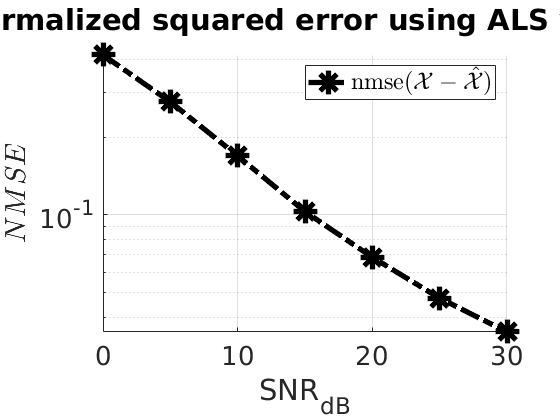

fig = figure();
ax = gca();
ax.FontName = 'Times New Roman';
ax.FontSize = 20;
ax.YAxis.Scale='log';
ax.XAxis.Label.String = 'SNR_{dB}';
ax.YAxis.Label.String = '$$NMSE$$';
ax.YAxis.Label.Interpreter = 'latex';
ax.Title.String = 'The normalized squared error using ALS vs. SNR_{dB}';
grid on;
hold on;
plot(all_snr, all_nmse_X, 'LineWidth', 4, 'Color', "black","LineStyle","-.","Marker","*","MarkerSize",18);
legend('nmse$$(\mathbf{\mathcal{X}} - \hat{\mathbf{\mathcal{X}}})$$', 'Interpreter','latex');
hold off;

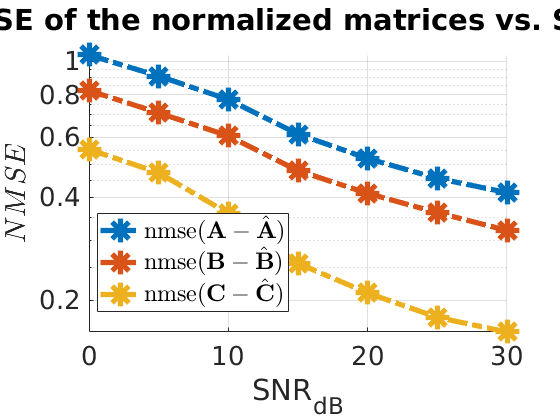

fig = figure();
ax = gca();
ax.FontName = 'Times New Roman';
ax.FontSize = 20;
ax.YAxis.Scale='log';
ax.XAxis.Label.String = 'SNR_{dB}';
ax.YAxis.Label.String = '$$NMSE$$';
ax.YAxis.Label.Interpreter = 'latex';
ax.Title.String = 'NMSE of the normalized matrices vs. SNR_{dB}';
grid on;
hold on;
plot(all_snr, all_nmse_all_A, 'LineWidth', 4,"LineStyle","-.","Marker","*","MarkerSize",18);
legend({'nmse$$(\mathbf{A} - \hat{\mathbf{A}})$$', 'nmse$$(\mathbf{B} - \hat{\mathbf{B}})$$', 'nmse$$(\mathbf{C} - \hat{\mathbf{C}})$$'}, 'Interpreter','latex', "Location", "best");
hold off;

#### Conclusion

- The uniqueness of the decomposition ($\hat{\mathbf{A}} \simeq \mathbf{A}$, $\hat{\mathbf{B}} \simeq \mathbf{B}$, $\hat{\mathbf{C}} \simeq \mathbf{C}$) happens if and only if we take into account three major issues: 1- Normalizing the column matrices by 1. In that case, the core tensor must compensate for the normalization in its super-diagonal. 2- As the sum of the factors can appear in any order, the columns of the matrices may be permuted. 3- The columns values can also be inverted as its norm is insensitive to signal inversion

- Precise CP approximation, that is, $\underline{\mathbf{X}} \simeq \underline{\hat{\mathbf{X}} }$

function [tenlambda, all_A_normalized, all_nse, n_iter]= als(tenX, R, max_iter)
arguments
    tenX;
    R;
    max_iter double = 1e3;
end
all_nse = zeros(1,max_iter);
N = ndims(tenX);
delta_min = 1e-6;
%% instantiating all_A
try
    % all n-mode unfolding of tenX
    all_unfoldX = cellfun(@nmodeunfold,{tenX,tenX,tenX},num2cell(1:N), 'UniformOutput', false);
    % all left singular vectors for each n-mode unfolding
    [all_U, ~, ~] = cellfun(@svd, all_unfoldX, 'UniformOutput', false);
    % instantiating all_A with the R leading vectors of all_U
    all_A_current = cellfun(@(x)x(:,1:R), all_U, 'UniformOutput', false);
catch ME % it was not possible to instantiate the A(n)'s as the R leading left vector of [tenX]_(n), use random matrices instead.
    if strcmp(ME.identifier,'MATLAB:badsubscript')
        all_A_current = cellfun(@randn, cellfun(@(x,y)[x,y], num2cell(size(tenX)), num2cell(R*ones(1,R)), 'UniformOutput', false), 'UniformOutput', false);
    end
end

%% computing current nmse
all_A_but_1_flipped = flip(all_A_current(setdiff(1:N,1)));
tenX_mode1_hat = all_A_current{1}*kr(all_A_but_1_flipped{:}).';
nse_current = norm(nmodeunfold(tenX,1)-tenX_mode1_hat)/norm(nmodeunfold(tenX,1));

%% the ALS
for n_iter=1:max_iter
    [all_A_new, all_A_normalized] = deal(all_A_current);
    for n=1:N
        % A(1), A(2), ..., A(n-1), A(n+1), ..., A(N)
        all_A_but_n = all_A_normalized(setdiff(1:N,n));
        % V <-  A(1)^TA(1) ⊙ A(2)^TA(2) ⊙ ... A(n-1)^TA(n-1) ⊙ A(n+1)^TA(n+1) ⊙ ... ⊙ A(N)^TA(N)
        V = cellfun(@(x)x.'*x, all_A_but_n, 'UniformOutput', false);
        V = times(V{:});
        % A_hat(n) <- X_mode_n*(A(N) ⊙ A(N-1) ⊙ ... A(n+1) ⊙ A(n-1) ⊙ ... ⊙ A(1))*V^†
        flipped_all_A_but_n = flip(all_A_but_n);
        all_A_new{n} = all_unfoldX{n}*kr(flipped_all_A_but_n{:})/V;
        % normalizing the new estimation of A(n)
        all_A_normalized{n} = normc(all_A_new{n});
    end
    % since the lambda is rewritten at each loop, save it only after the for ends 
    lambda_diag = vecnorm(all_A_new{N});

    %% computinng the new nse
    all_A_but_1_flipped = flip(all_A_normalized(setdiff(1:N,1)));
    % [X_hat]_(1) <- A(1) * diag(lambda) * (A(3)◇A(2))^T
    tenX_mode1_hat = all_A_normalized{1} * diag(lambda_diag) * kr(all_A_but_1_flipped{:}).';
    nse_new= norm(nmodeunfold(tenX,1)-tenX_mode1_hat)/norm(nmodeunfold(tenX,1));

    %% assessing the new result
    all_nse(n_iter) = nse_current;
    if nse_new < nse_current % it had improvement error_new<error_current, save the new ones as the current solution
        nse_current = nse_new;
        all_A_current = all_A_new;
        if all_nse(n_iter)-nse_new < delta_min % the improvement has reached its benchmark, break the loop
            break
        end
    else % the iteration stopped giving any improvement, break the loop
        break
    end
end
%% max iteration has reached or the loop has broken, computing lambda by normalizing all_A
all_nse = all_nse(1:n_iter); % truncating the all_nse to its useful part
% vectorization of tenlambda
lambda_vec = zeros(R^N,1);
lambda_vec(1:R^2+R+1:R^N) = lambda_diag; % fill the main diagonal of tenlambda
% tensorization of lambda_vec
tenlambda = reshape(lambda_vec, R*ones(1,N));
end

function [all_A_out, tenlambda_out] = get_opt_permutation(all_A, tenX, all_A_hat, tenlambda_hat)
N = numel(all_A);
get_all_nse = @(A, A_hat)(sum(cellfun(@(x,y)(norm(x-y)/norm(x)), A, A_hat))/numel(A));

%% looking for the best permutation
all_permutation = mat2cell(perms(1:N), ones(1, factorial(N)), N).';
nmse_current = inf;

for permutation=all_permutation
    [p(1:N)] = deal(permutation);
    all_A_permuted = cellfun(@(x,p)(x(:,p)), all_A_hat, p, 'UniformOutput', false);
    vec_outprod = get_vec_outprod(all_A{:});
    vec_outprod_permuted = get_vec_outprod(all_A_permuted{:});
    all_tensors_factors = cellfun(@(x)outprod(x{:}), vec_outprod, 'UniformOutput', false);
    all_tensors_factors_permuted = cellfun(@(x)outprod(x{:}), vec_outprod_permuted, 'UniformOutput', false);
    all_nmse_new = cellfun(@norm, cellfun(@(x,y)tensor(x-y),all_tensors_factors, all_tensors_factors_permuted, 'UniformOutput', false), 'UniformOutput', false);
    nmse_new = sum([all_nmse_new{:}])/numel(all_nmse_new);
    
    if nmse_new < nmse_current
        nmse_current = nmse_new;
        all_A_out = all_A_permuted;
        best_permutation = permutation{1};
    end
end

%% looking for the inversions
% +1 factors
all_A_out1 = cellfun(@minus, all_A, all_A_out, 'UniformOutput', false);
all_A_out1 = cellfun(@vecnorm, all_A_out1, 'UniformOutput', false);
is_1 = cat(1,all_A_out1{:});
% -1 factors
all_A_out_minus1 = cellfun(@plus, all_A, all_A_out, 'UniformOutput', false);
all_A_out_minus1 = cellfun(@vecnorm, all_A_out_minus1, 'UniformOutput', false);
is_minus1 = cat(1,all_A_out_minus1{:});

% inverting the lambda
non_inversion_table = is_1<is_minus1;
mult_lamb_fac = sum(non_inversion_table);
mult_lamb_fac = bsxfun(@rem, mult_lamb_fac, 2);
mult_lamb_fac = mult_lamb_fac.*2 - 1;

tenlambda_out = tenlambda_hat;
supdiag_lambda = tenlambda_hat(tenlambda_hat~=0);
tenlambda_out(tenlambda_out~=0) = supdiag_lambda(best_permutation).*mult_lamb_fac.';
% inverting the all_A_out columns
non_inversion_table = mat2cell(non_inversion_table, ones(1,size(non_inversion_table,1)), size(non_inversion_table,2));
all_A_out = cellfun(@(x,y)x.*(2*y-1), all_A_out, non_inversion_table.', 'UniformOutput', false);

    function all_vec = get_vec_outprod(varargin)
        all_vec = cell(1, size(varargin{1},2));
        
        for i=1:numel(all_vec)
            all_vec{i} = cell(1,numel(varargin));
            for j=1:numel(varargin)
                all_vec{i}{j} = varargin{j}(:,i);
            end
        end
    end

end